# **Vehicle Performance Analysis (CoDPAD M1-2)**

CoDPAD module 1-2 : Vehicle performance analysis - Basic vehicle characteristics analysis

This part suggests results achieved from fligth test based on refSigTest. Results from raw response data to estimated transfer function will be provided. Please refer to CoDPAD document Ch. 1.1. for further details.

cd(fileparts(matlab.desktop.editor.getActiveFilename))

## User Input

dataTypeToRefer = 0

dataTypeToRefer = 0

tfFile = load("tfResult.mat")

tfFile = struct with fields:
    tfResult: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}


heaveTfResult = load("heaveTf.mat")

heaveTfResult = struct with fields:
    heaveTfResult: [1×1 struct]


covResult = load("covResult.mat")

covResult = struct with fields:
    covResult: [1×1 struct]


covSampleNum = 100000

covSampleNum = 100000

confidence = "0.9"

confidence = "0.9"

covResult = covResult.covResult;
heaveTfResult = heaveTfResult.heaveTfResult;
tfTemp = tfFile.tfResult;

isSweep = dataTypeToRefer;
if isSweep
    if isSweep == 1
        tfTemp(1:9) = [];
    end
end

tfData{1} = tfTemp{1};
tfData{2} = tfTemp{4};
tfData{3} = tfTemp{7};
tfData{4} = tfTemp{2};
tfData{5} = tfTemp{5};
tfData{6} = tfTemp{8};
tfData{7} = tfTemp{3};
tfData{8} = tfTemp{6};
tfData{9} = tfTemp{9};

dataSize = size(tfData,2);


## Basic Dynamic Characteristic Analysis

stepResult = {}; phaseResult = {};
for i = 1:dataSize
    sys = tf(tfData{i}.Num,tfData{i}.Den,'ioDelay',tfData{i}.Delay);
    stepResult{i} = stepinfo(sys);
    [gm,pm,wg,wp] = margin(sys);
    phaseResult{i} = [gm,pm,wg,wp,bandwidth(sys)];
end

#### Step response

stepResultTable = [];
for i = 1:dataSize
    stepResultTable(i,1) = stepResult{i}.RiseTime;
    stepResultTable(i,2) = stepResult{i}.SettlingTime;
    stepResultTable(i,3) = stepResult{i}.Overshoot;
    stepResultTable(i,4) = stepResult{i}.Peak;
    temp = step(tf(tfData{i}.Num,tfData{i}.Den,'ioDelay',tfData{i}.Delay));
    stepResultTable(i,5) = 1 - temp(end);
end

Rise time

Settling time

Overshoot

Peak

SSE

columns = {'Rise time','Settling time','Overshoot','Peak','SSE'};
rows = {'Roll','Pitch','Yaw','u','v','w','X','Y','Z'};
T = table(stepResultTable(:,1),stepResultTable(:,2),stepResultTable(:,3),stepResultTable(:,4),stepResultTable(:,5),'Rownames',rows);
T.Properties.VariableNames = columns

T = 9×5 table
             Rise time    Settling time    Overshoot     Peak          SSE    
             _________    _____________    _________    _______    ___________

    Roll      0.11269        0.43734        9.2489        1.033       0.057749
    Pitch     0.11716        0.83243        18.366       1.0671        0.10045
    Yaw       0.31342        0.98953        4.4529       1.0505       -0.00425
    u         0.41125         3.3962        19.932       1.1991    -0.00094484
    v         0.45583         1.4858        6.2822       1.1276      -0.057896
    w         0.58288          1.619        3.6495       1.0336      0.0025296
    X          8.0355         14.707             0      0.96308 

#### Frequency response

phaseResultTable = [];
for i = 1:dataSize
    phaseResultTable(i,1) = phaseResult{i}(1);
    phaseResultTable(i,2) = phaseResult{i}(2);
    phaseResultTable(i,3) = phaseResult{i}(3);
    phaseResultTable(i,4) = phaseResult{i}(4);
    phaseResultTable(i,5) = phaseResult{i}(5);
end

Bandwidth

GM - PM

columns = {'Gain Margin','Phase Margin','BandWidth'};
rows = {'Roll','Pitch','Yaw','u','v','w','X','Y','Z'};
T = table(phaseResultTable(:,1),phaseResultTable(:,2),phaseResultTable(:,5),'Rownames',rows);
T.Properties.VariableNames = columns

T = 9×3 table
             Gain Margin    Phase Margin    BandWidth
             ___________    ____________    _________

    Roll       1.6113             Inf         18.624 
    Pitch      1.9802           92.91         14.991 
    Yaw        5.0872          140.09         6.6292 
    u          3.4593          109.52         4.2125 
    v          3.4674          101.76         4.6558 
    w          11.575             Inf         3.6542 
    X          15.581             Inf        0.27279 
    Y          33.005             Inf        0.44507 
    Z          56.836          122.75        0.16573 


## Rotating Wing Vehicle flight Performance

#### TRC (Translational Rate Command)

#### Heave response

#### Axis coupling

rows = {'TRC_u';'TRC_v';'Heave Response'};
c1 = [stepResult{4}.RiseTime;stepResult{5}.RiseTime;1/heaveTfResult.Den(2)];
table(c1,'Rownames',rows)

ans = 3×1 table
                        c1   
                      _______

    TRC_u             0.41125
    TRC_v             0.45583
    Heave Response     0.3381


## Disturbance Rejection Performance

#### 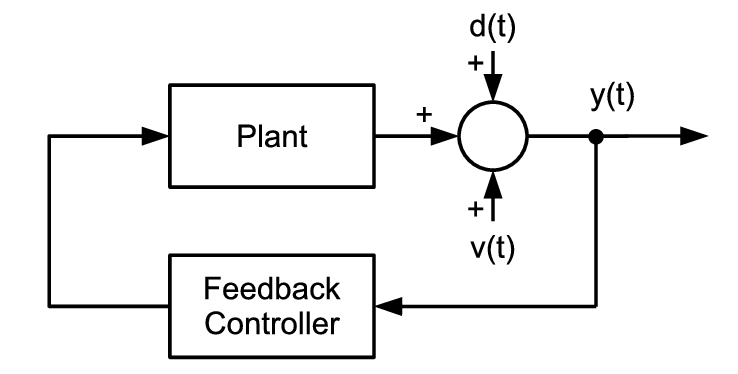

Response of this model can be calculated using,


$$y=\;\frac{\mathrm{DG}}{\mathrm{DGH}}C+\frac{G}{\mathrm{DGH}}W$$


Tranfer function of latter part is called 'sensitivity transfer function' 


$$\frac{G}{\textrm{DGH}}$$


This segment tells us how the system reacts to disturbances. By drawing the Bode plot of this transfer function, DRB and DRP are acquired.

#### DRB

FutureWork

#### DRP

FutureWork

## State Holding Performance

% Internal parameters : DO NOT TOUCH
level = 1-confidence;
zRange = 5;
cumulated = 0;
index = [];
peripheral = [];
density = 500;

% Load data
stateSize = size(covResult.pos,1);
posHoldSampleData = mvnrnd(zeros(stateSize,1),covResult.pos,covSampleNum);
velHoldSampleData = mvnrnd(zeros(stateSize,1),covResult.vel,covSampleNum);



### Hovering

#### Attitude error variance analysis

#### Attitude error PSD

#### Position error variance analysis

#### Position error PSD

#### Roll-Pitch attitude error distribution

#### Vehicle pointing error distribution

### Cruising

#### Attitude error variance analysis

#### Position error variance analysis

#### Attitude error PSD (Power Spectral Density)

#### Roll-Pitch attitude error distribution

#### Vehicle pointing error distribution

## Function definition

function flag = boxed(n,index,xGridSize,yGridSize)
x = index(n,1); y = index(n,2);
right = 0; left = 0; up = 0; down = 0;
flag = 0;

if isempty(find(abs(index(:,1)-(x+xGridSize)) < xGridSize/2 & abs(index(:,2)-y) < yGridSize/2,1))
    right = 1;
end
if isempty(find(abs(index(:,1)-(x-xGridSize)) < xGridSize/2 & abs(index(:,2)-y) < yGridSize/2,1))
    left = 1;
end
if isempty(find(abs(index(:,1)-x) < xGridSize/2 & abs(index(:,2)-(y+yGridSize)) < yGridSize/2,1))
    up = 1;
end
if isempty(find(abs(index(:,1)-x) < xGridSize/2 & abs(index(:,2)-(y-yGridSize)) < yGridSize/2,1))
    down = 1;
end

if up || down || right || left
    flag = 1;
end

end